# Cours 12.10.22

## Chapitre 2 : Recherche de zéros

## Exemple. trouverles zéros de la f(x) = 3*x + sin(x) - exp(x)

Par méthode Bissection

% 1. Dessiner la fonction pour trouver les 0 approximatifs
f = @(x) 3*x+sin(x)-exp(x)

f = function_handle with value:
    @(x)3*x+sin(x)-exp(x)

f(1)

ans = 1.1232

f(2)

ans = -0.4798

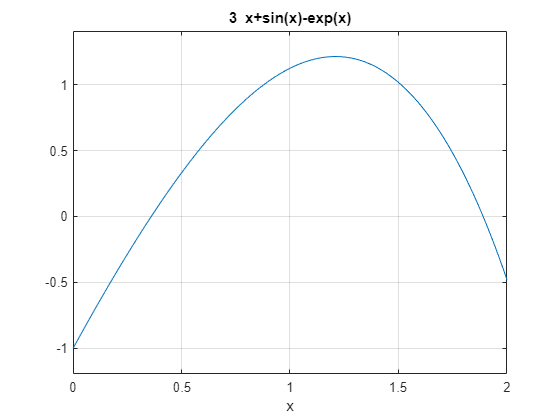

ezplot(f, [0,2])
grid on



% Résolution par matlab : fzero
x1 = fzero(f, 0.3)

x1 = 0.3604

f(x1)

ans = 0

x2 = fzero(f, 1.9)

x2 = 1.8900

f(x2)

ans = 0



% Par méthode bissection (méthode custom)
bissection(0.2, 1, 1e-8, f)

ans = 0.3604

f(ans)

ans = -1.7377e-09

bissection(1.5, 2, 1e-8, f)

ans = 1.8900

f(ans)

ans = -5.5311e-08